% Generate ECG signal
duration   = 10;
fs         = 1000;
beat_every = 1;

t   = 0 : 1/fs : duration;
tau = mod(t, beat_every);

a1 =  0.25;  b1 = 0.09;   c1 = 0.015;
a2 = -0.2;   b2 = 0.185;  c2 = 0.008;
a3 =  1.6;   b3 = 0.20;   c3 = 0.012;
a4 = -0.4;   b4 = 0.215;  c4 = 0.008;
a5 =  0.4;   b5 = 0.40;   c5 = 0.04;

scale = 1 / 1.6;

ecg = scale * ( a1 .* exp(-((tau - b1)./c1).^2) + ...
                a2 .* exp(-((tau - b2)./c2).^2) + ...
                a3 .* exp(-((tau - b3)./c3).^2) + ...
                a4 .* exp(-((tau - b4)./c4).^2) + ...
                a5 .* exp(-((tau - b5)./c5).^2) );

## Generated ECG 

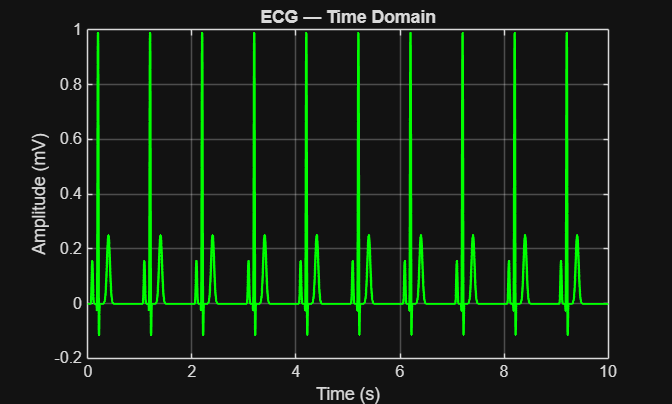


% ---- Package for Simulink ----
ecg_sim.time            = t';               % column vector
ecg_sim.signals.values  = ecg';             % column vector
ecg_sim.signals.dimensions = 1;

% ---- Plot ----
figure;
plot(t, ecg, 'g', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Amplitude (mV)');
title('ECG — Time Domain');
grid on;

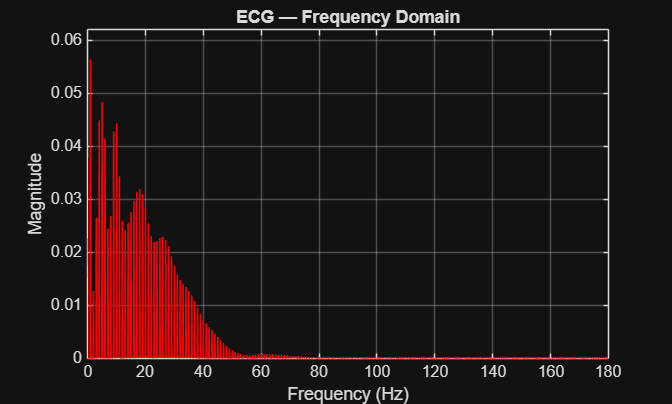


% ---- Frequency Analysis (FFT) ----
L = length(ecg);
Y = fft(ecg);

% Two-sided → single-sided spectrum (LINEAR, not dB)
P2 = abs(Y / L);
P1 = P2(1:floor(L/2)+1);
P1(2:end-1) = 2 * P1(2:end-1);

f = fs * (0:(floor(L/2))) / L;

% ---- Plot Frequency Domain ----
figure;
plot(f, P1, 'r', 'LineWidth', 1.0);
title('ECG — Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
xlim([0 180]);
ylim([0 max(P1)*1.1]);

## Generated ECG "Noisy + Amplfied" 

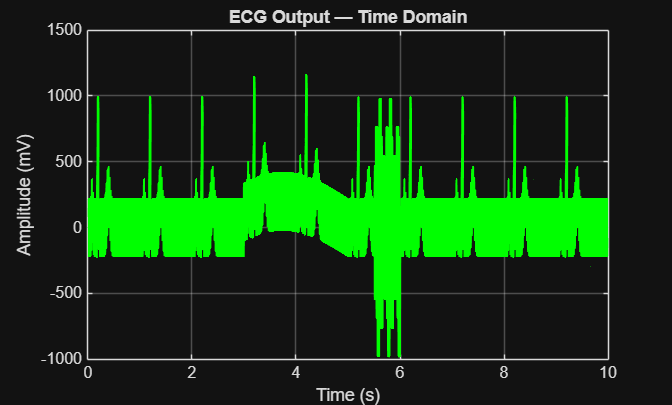

% ---- Extract data from Simulink timeseries ----
t_out   = out.ecg_amplified.Time;           % time vector (s)
ecg_out = out.ecg_amplified.Data;           % signal values
ecg_out = ecg_out(:)';                  

% ---- Compute sampling frequency from output time vector ----
fs_out = 1 / mean(diff(t_out));         

% TIME DOMAIN
figure;
plot(t_out, ecg_out, 'g', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude (mV)');
title('ECG Output — Time Domain');
grid on;

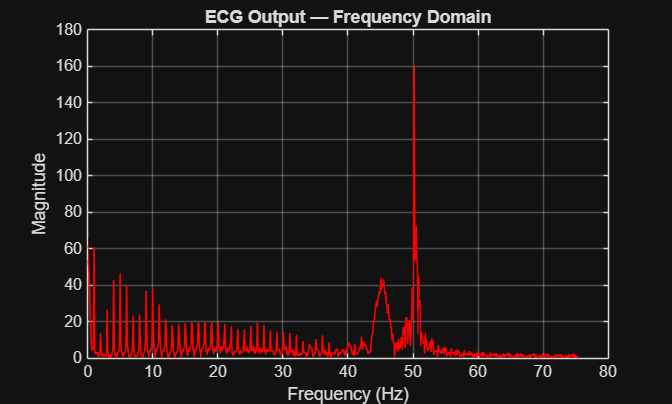


% FREQUENCY DOMAIN
L   = length(ecg_out);
Y   = fft(ecg_out);
P2  = abs(Y / L);
P1  = P2(1:floor(L/2)+1);
P1(2:end-1) = 2 * P1(2:end-1);
f   = fs_out * (0:floor(L/2)) / L;

figure;
plot(f, P1, 'r', 'LineWidth', 1.0);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('ECG Output — Frequency Domain');
grid on;

## ECG "Filtered"

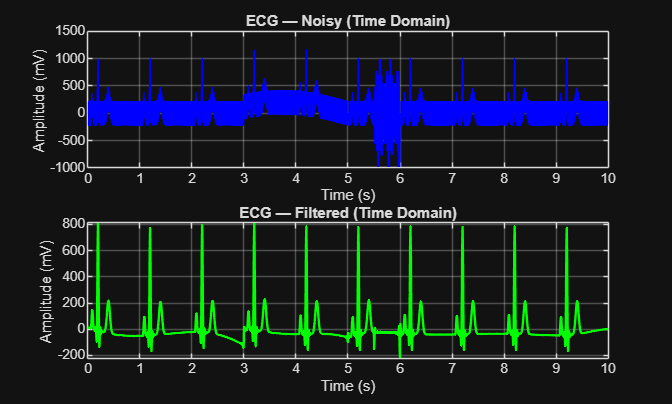

% ---- Extract Simulink output ----
t_out   = out.ecg_amplified.Time;
ecg_out = out.ecg_amplified.Data(:)';
fs_out  = 1 / mean(diff(t_out));

% ================================================
% FILTER 1: High-Pass — Remove Baseline Wander
% Baseline wander is at 0.2 Hz → cutoff at 0.5 Hz
% ================================================
order_hp = 4;
fc_hp    = 0.5;                          % Hz
Wn_hp    = fc_hp / (fs_out/2);          % Normalized (0 to 1)
[b_hp, a_hp] = butter(order_hp, Wn_hp, 'high');
ecg_hp = filtfilt(b_hp, a_hp, ecg_out); % Zero-phase filtering

% ================================================
% FILTER 2: Low-Pass — Remove Muscle Artifact
% Muscle artifact at 45 Hz → cutoff at 30 Hz
% ================================================
order_lp = 4;
fc_lp    = 30;                           % Hz
Wn_lp    = fc_lp / (fs_out/2);
[b_lp, a_lp] = butter(order_lp, Wn_lp, 'low');
ecg_lp = filtfilt(b_lp, a_lp, ecg_hp); % Apply after HP

% ================================================
% FILTER 3: Notch — Remove Powerline at 50 Hz
% ================================================
notch_freq = 50;                         % Hz
bandwidth  = 1;                          % Hz (narrow notch)
Wn_notch   = [notch_freq - bandwidth/2, notch_freq + bandwidth/2] / (fs_out/2);
[b_n, a_n] = butter(2, Wn_notch, 'stop');
ecg_clean  = filtfilt(b_n, a_n, ecg_lp); % Final clean signal

% ================================================
% PLOT: Original vs Filtered — Time Domain
% ================================================
figure;
subplot(2,1,1);
plot(t_out, ecg_out, 'b', 'LineWidth', 1);
title('ECG — Noisy (Time Domain)');
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;

subplot(2,1,2);
plot(t_out, ecg_clean, 'g', 'LineWidth', 1.5);
title('ECG — Filtered (Time Domain)');
xlabel('Time (s)'); ylabel('Amplitude (mV)'); grid on;

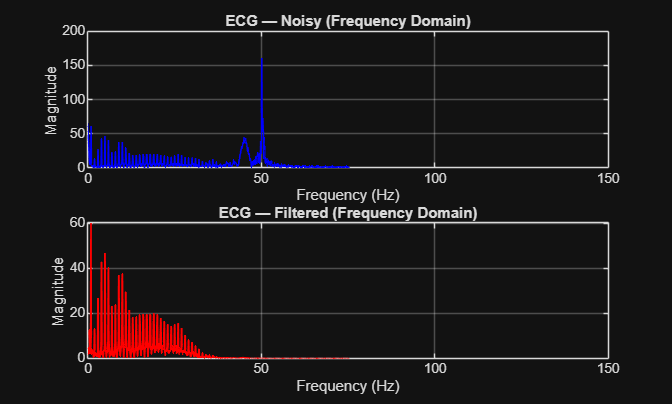


% ================================================
% PLOT: Original vs Filtered — Frequency Domain
% ================================================
L = length(ecg_out);
f = fs_out * (0:floor(L/2)) / L;

get_P1 = @(sig) deal( 2*abs(fft(sig)/L), f );

P1_noisy = abs(fft(ecg_out)/L);
P1_noisy = P1_noisy(1:floor(L/2)+1);
P1_noisy(2:end-1) = 2*P1_noisy(2:end-1);

P1_clean = abs(fft(ecg_clean)/L);
P1_clean = P1_clean(1:floor(L/2)+1);
P1_clean(2:end-1) = 2*P1_clean(2:end-1);

figure;
subplot(2,1,1);
plot(f, P1_noisy, 'b', 'LineWidth', 1);
title('ECG — Noisy (Frequency Domain)');
xlabel('Frequency (Hz)'); ylabel('Magnitude'); grid on;
xlim([0 150]);

subplot(2,1,2);
plot(f, P1_clean, 'r', 'LineWidth', 1.2);
title('ECG — Filtered (Frequency Domain)');
xlabel('Frequency (Hz)'); ylabel('Magnitude'); grid on;
xlim([0 150]);

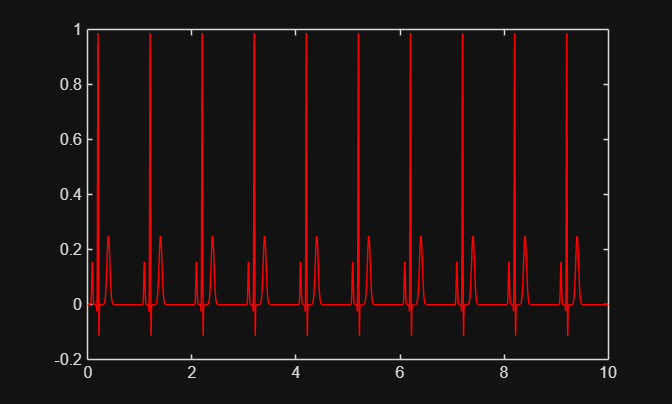

figure;
plot(t,ecg, 'r')

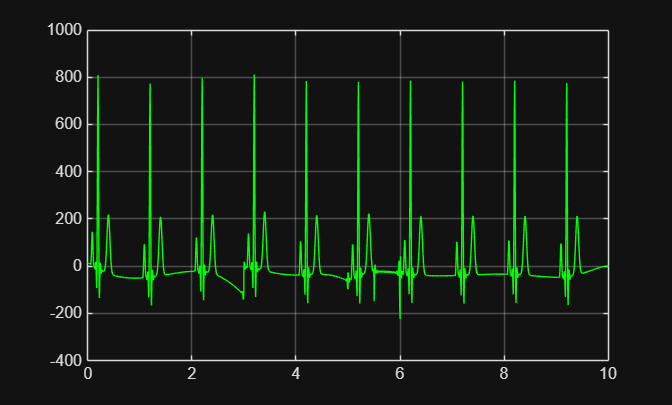

plot(t_out, ecg_clean,'g')
grid on

## Heart beats & R-R Peaks Calculations

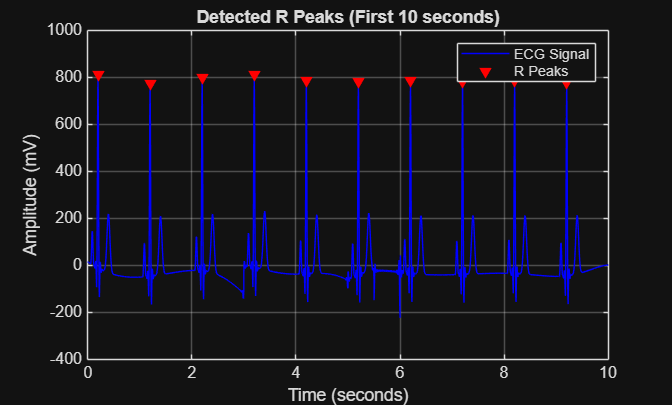

% ---- Heart Beats & R-R Peak Calculations ----
% Use the filtered Simulink signal (ecg_clean) for R-peak detection
time_vector = t_out;
ecg_notch   = ecg_clean;
Fs          = fs_out;

%% =========================
% Member 3 — R Peak Detection
%% =========================

% Work on the first 10 seconds so the plot stays clear
tEnd   = 10;
idx10  = time_vector <= tEnd;

t10   = time_vector(idx10);
ecg10 = ecg_notch(idx10);

%% Detect R peaks
[pks, locs] = findpeaks(ecg10, ...
    'MinPeakDistance', round(0.4*Fs), ...   % prevent peaks that are too close
    'MinPeakProminence', 0.25);             % prevent noise from being detected

% Keep only the TOP 10 R-peaks by amplitude
maxPeaks = 10;
[pks_sorted, sort_idx] = sort(pks, 'descend');   % sort all peaks highest → lowest
top_idx  = sort_idx(1:min(maxPeaks, end));        % keep indices of top 10

% Re-sort by time so RR intervals are chronological
top_idx  = sort(top_idx);
pks  = pks(top_idx);
locs = locs(top_idx);

%% Plot ECG with detected R-peaks
figure
plot(t10, ecg10, 'b')
hold on
plot(t10(locs), pks, 'rv', 'MarkerFaceColor', 'r')

xlabel('Time (seconds)')
ylabel('Amplitude (mV)')
title('Detected R Peaks (First 10 seconds)')
legend('ECG Signal', 'R Peaks')
grid on


%% RR intervals
RR = diff(t10(locs));

%% Heart Rate calculation
HR     = 60 ./ RR;
meanHR = mean(HR);

%% Display results
disp('--- Member 3 Results ---')

--- Member 3 Results ---


disp(['Number of R-peaks in 10s:  ', num2str(length(pks))])

Number of R-peaks in 10s:  10


disp(['RR Intervals (s):          ', num2str(RR(:)')])

RR Intervals (s):          1           1           1           1           1           1           1           1           1


disp(['Mean Heart Rate (bpm):     ', num2str(meanHR)])

Mean Heart Rate (bpm):     60
